# Getting started with the MATLAB PBPK toolbox

The MATLAB PBPK toolbox provides an easy-to-use scripting interface to define and execute PBPK modelling workflows.

### Setup

Once `matpbpk` is downloaded and installed, type

initmatpbpk()



 --------------------------------------------------------------- 
|                 matpbpk: MATLAB PBPK toolbox                  |
|                                                               |
|             (c) Niklas Hartung, Wilhelm Huisinga              |
|                   University of Potsdam, 2024                 |
|                                                               |
|  The program is distributed under the terms of the            |
|  BSD 2-Clause License (see file license.txt).                 |
|                                                               |
|  This is the development version of the Matlab PBPK toolbox.  |
|  If you wish to use the toolbox for your research, please     |
|  contact us. The toolbox is under active development;         |
|  some features might change in the future.                    |
|                                                               |
 --------------------------------------------------------------- 


Initia

to load the physiology database, the drug database and the unit computation system into memory.

### Example usage

Below is a simple script to define and run a PBPK model simulation. More complex simulation scripts can found in the `examples` folder.

Define physiology, dosing, sampling, model

obs = PBPKobservables();
indv = Individual('Virtual');
indv.physiology = Physiology('human35m');
indv.dosing = Oral('Warfarin',(0:7)*u.day, 250*u.mg);
indv.drugdata = loaddrugdata('Warfarin','species','human');
indv.sampling = Sampling(2*u.day:30*u.min:8*u.day, obs);
indv.model = sMD_PBPK_12CMT_wellstirred;
indv.model.options.tissuePartitioning = @rodgersrowland;

Next, initialize, simulate, plot:

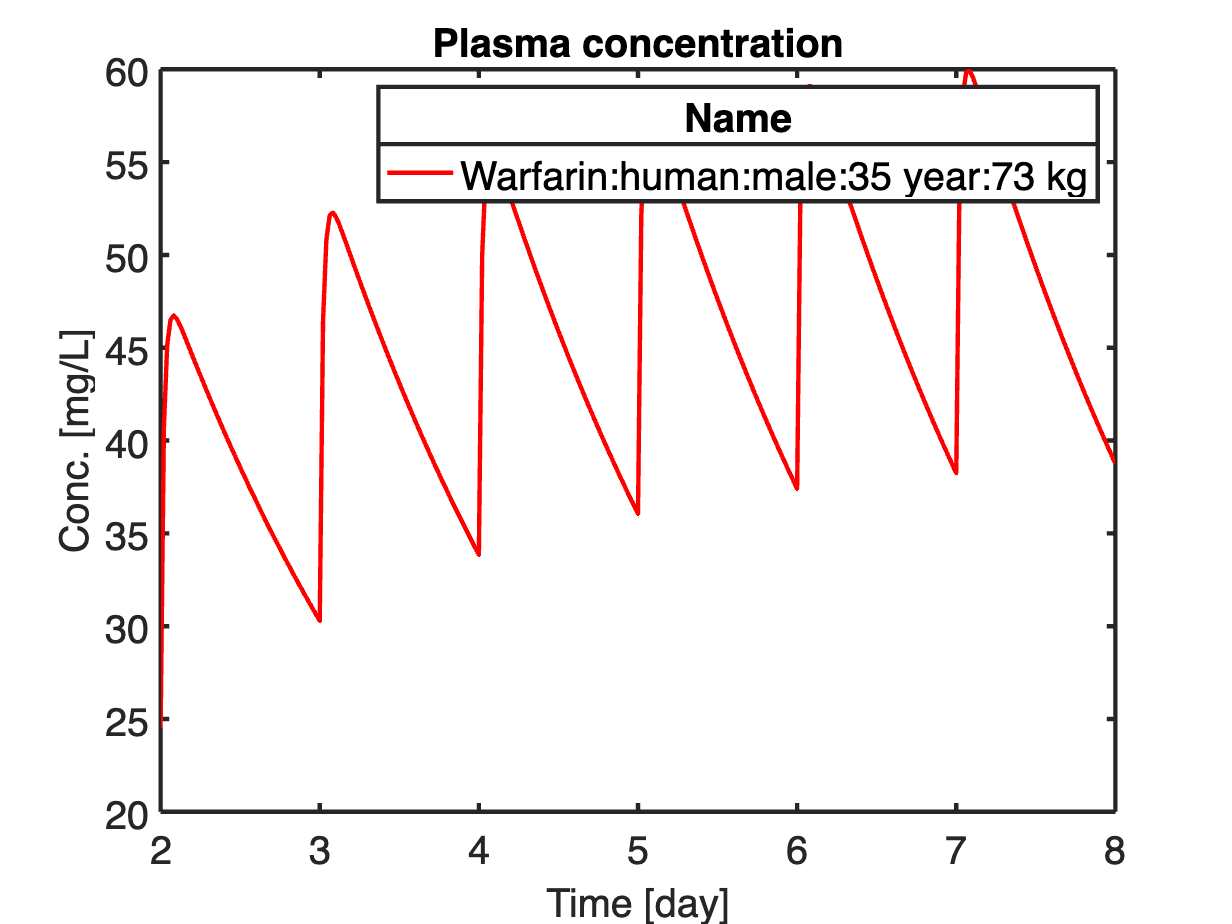

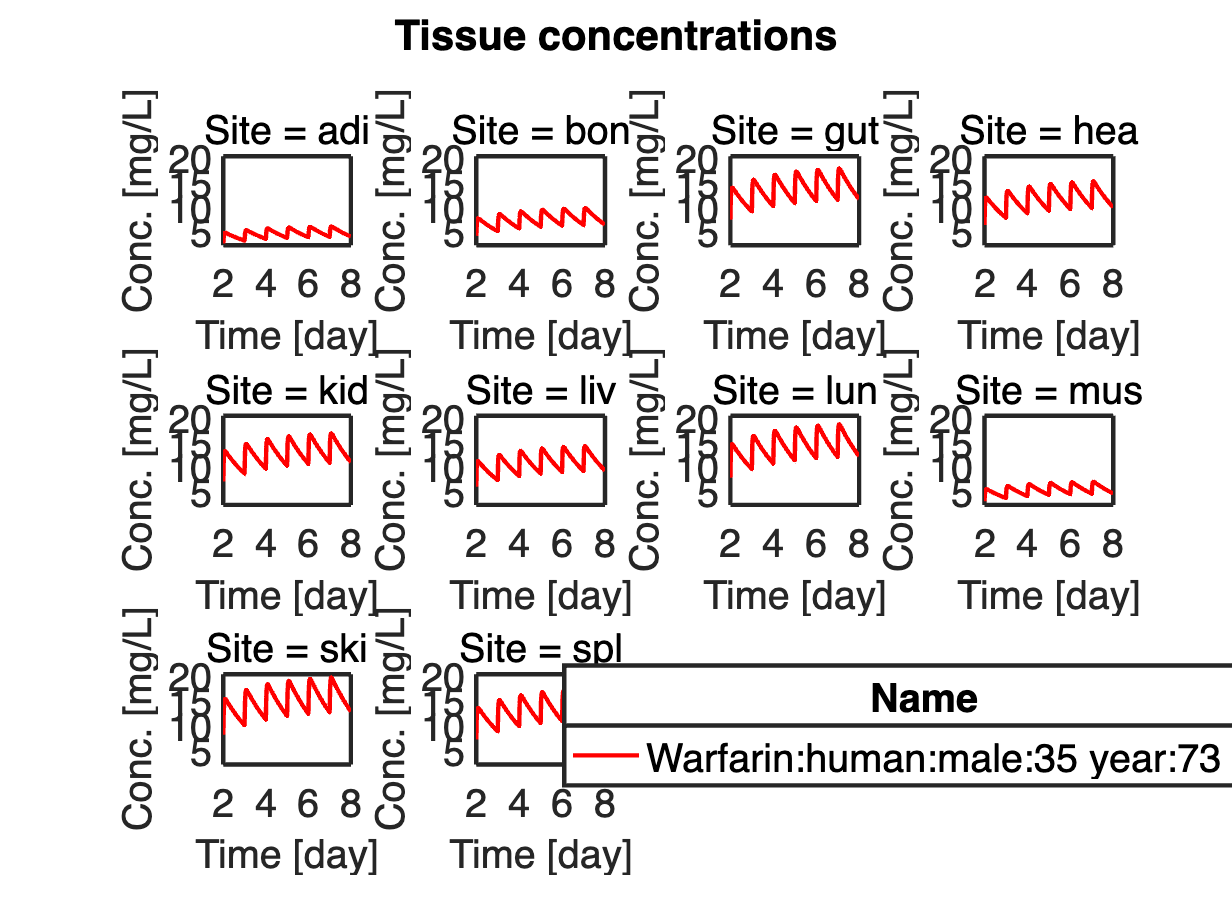

initialize(indv)
simulate(indv)
plot(indv, 'yunit', 'mg/L')